# Sistema de Ecuaciones Lineales

## Aplicación 1

El sector agropecuario holandés, junto con la totalidad del complejo agroalimentario (producción, transformación, comercialización), arrojó una producción bruta de algo más de 36000 millones de florines en 1992, cifra que tras descontar la adquisición de los medios de producción, las amortizaciones y diversa tasas e impuestos se convirtió en 17400 millones de valor agregado bruto y casi 13000 millones de valor agregado neto. Es por tal motivo que un granjero desea preparar una fórmula alimenticia para engordar ganado para ello deberá de modelar un sistema de ecuaciones lineales. Dispone de maíz, desperdicios, alfalfa y cebada, cada uno con ciertas unidades de ingredientes nutritivos, de acuerdo con la tabla siguiente:

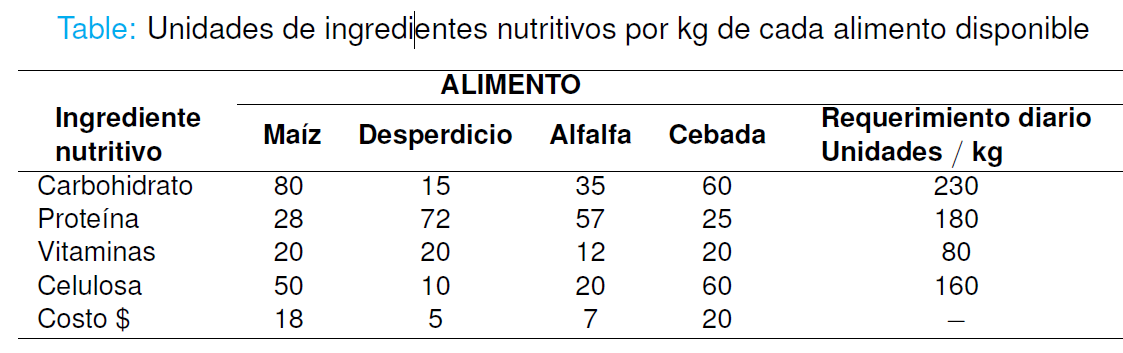

### Preguntas:

#### Pregunta 1:

Determine un sistema de ecuaciones lineales con 4 incognitas de la forma

P x X = Q donde el vector columna X representa los kilogramos necesarios

de cada ingrediente (en el orden y numéricamente igual al presentado en la

tabla) para satisfacer en su totalidad el requerimiento diario. De como

respuesta la traza de la matriz P.

Solución:

Definición de variables:

$x_1:$ Cantidad de Kilogramos de Maíz

$x_2:$ Cantidad de Kilogramos de Desperdicio

$x_3$: Cantidad de Kilogramos de Alfalfa

$x_4$: Cantidad de Kilogramos de Cebada


$$80x_1 + 15x_2+35x_3+60x_4=230$$



$$28x_1 + 72x_2+57x_3+25x_4=180$$



$$20x_1 + 20x_2+12x_3+20x_4=80$$



$$50x_1 + 10x_2+20x_3+60x_4=160$$


### *Forma Matricial*

$P=\left(\begin{array}{|||||}80&15&35&60\\28&72&57&25\\20&20&12&20\\50&10&20&60\\\end{array}\right)$, $X=\left (\begin{array}{|}x_1\\x_2\\x_3\\x_4\end{array}\right)$, $Q=\left(\begin{array}{|}230\\180\\80\\160\end{array}\right)$

P=[80 15 35 60; 28 72 57 25; 20 20 12 20; 50 10 20 60]

P =     80    15    35    60
    28    72    57    25
    20    20    12    20
    50    10    20    60


Q=[230;180;80;160]

Q =    230
   180
    80
   160


trace(P)

ans = 224

### Pregunta 2

Determine el rango de la matriz ***P*** y el rango de la matriz aumentada [***P***|***Q***]

RangoP=rank(P)

RangoP = 4

Pa=[P Q]

Pa =     80    15    35    60   230
    28    72    57    25   180
    20    20    12    20    80
    50    10    20    60   160


RangoPa=rank(Pa)

RangoPa = 4

### Pregunta 3

Determine si el sistema $P*X=Q$ tiene solución única, infinita soluciones o no tiene solución. (Sugerencia. Utilice la función creada: RoucheFrobenius). Resolver el sistema de ecuaciones lineales si es compatible determinado.

Solución:

X=RoucheFrobenius(P,Q)

El sistema tiene solución única 
 x1 = 1.85
 x2 = 1.03
 x3 = 0.62


X =     1.8525
    1.0318
    0.6178
    0.7450


### Pregunta 4

Determine el costo de la mezcla

Solución:

CostoMezcla=18*X(1)+5*X(2)+7*X(3)+20*X(4)

CostoMezcla = 57.7289

### Pregunta 5

Otro granjero decide optimizar la formula original agregando 2 alimentos de

tipos A y B, estos nuevos alimentos contiene: Proteina, Vitaminas, Calcio y

Sales Minerales.

El de tipo A sólo contiene:

- Proteina, 50% mas que lo que contiene el maíz.

- Calcio, una proporción equivalente al de carbohidrato que contiene la Alfalfa.

- 25 unidades por kg en sales minerales.

El de tipo B sólo contiene:

- Vitaminas, un 5% mas que lo que contiene la cebada.

- Calcio, un equivalente de Proteina que contiene la cebada.

- 30 unidades por kg en sales minerales.

Estos nuevos productos aplican nuevos requerimientos diarios de ingredientes nutritivos.

**Complete la siguiente tabla con los datos mencionados.**

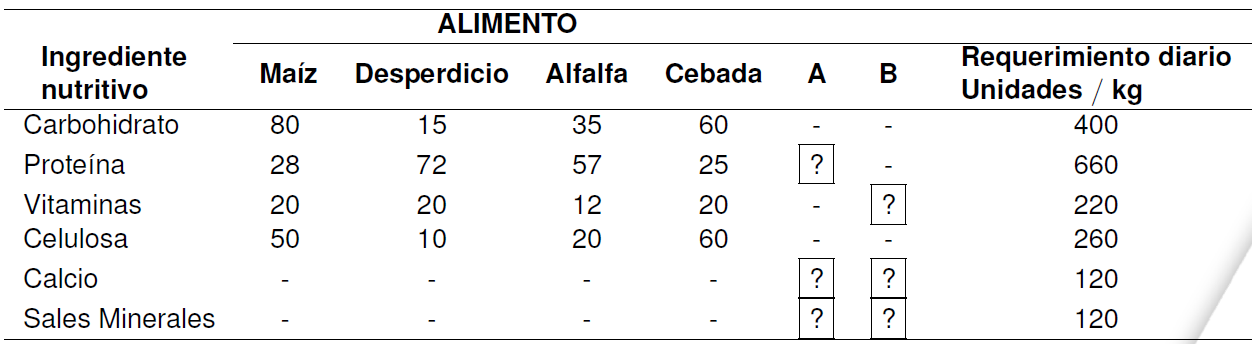

Solución:

$x_5$: Cantidad de Kilogramos del Tipo A.

$x_6$: Cantidad de Kilogramos del Tipo B.

$\left( \begin{array}{llllll}80&15&35&60&0&0\\28&72&57&25&42&0\\20&20&12&20&0&21\\50&10&20&60&0&0\\0&0&0&0&35&25\\0&0&0&0&25&30\end{array}\right)$$\left(\begin{array}{l}x_1\\x_2\\x_3\\x_4\\x_5\\x_6\end{array}\right)$= $\left(\begin{array}{l}400\\660\\220\\260\\120\\120\end{array}\right)$

### Pregunta 6

Utilizando los datos del item anterior, determine un sistema de 6 ecuaciones lineales con 6 incógnitas de la forma $M � Y = R$ donde el vector columna $Y$ representa los kilogramos necesarios de cada ingrediente (en el orden y numéricamente igual al presentado en la tabla) para satisfacer en su totalidad el requerimiento diario.

Halle la traza de la matriz M.

M = [80 15 35 60 0 0; 28 72 57 25 42 0; 20 20 12 20 0 21; 50 10 20 60 0 0; 0 0 0 0 35 25; 0 0 0 0 25 30]

M =     80    15    35    60     0     0
    28    72    57    25    42     0
    20    20    12    20     0    21
    50    10    20    60     0     0
     0     0     0     0    35    25
     0     0     0     0    25    30


R = [400; 660; 220; 260; 120; 120]

R =    400
   660
   220
   260
   120
   120


TrazaM = trace(M)

TrazaM = 289

Y=linsolve(M,R)

Y =     0.7097
    1.9790
    7.2543
    0.9940
    1.4118
    2.8235


### Pregunta 7:

Utilizando comandos de Matlab, construir una submatriz de M de orden $3 * 3$ denominada $P1$, considerando la 1era, 3era y 4ta fila de M, además la 1era, 2da y 4ta columana de $M$. Luego, realice las siguientes operaciones:

P1 = M([1 3 4], [1 2 4])

P1 =     80    15    60
    20    20    20
    50    10    60


Luego, realice las siguiente operaciones:

- Halle a traza de P1

trace(P1)

ans = 160

- Halle el determinante de P1

det(P1)

ans = 29000

- Halle la transpuesta de P1

P1'

ans =     80    20    50
    15    20    10
    60    20    60


- Halle la diagonal de P1

diag(P1)

ans =     80
    20
    60


- Intercambie la primera fila con la 3era fila en P1.

P1([1 3],: )=P1([3 1], :)

P1 =     50    10    60
    20    20    20
    80    15    60


- Intercambie la segunda columna con la tercera columna de P1

P1(:,[2 3]) = P1(:, [3 2])

P1 =     50    60    10
    20    20    20
    80    60    15


- Halle la matriz triángular inferior de P1

tril(P1)

ans =     50     0     0
    20    20     0
    80    60    15


- Halle la inversa de P1

inv(P1)

ans =    -0.0310   -0.0103    0.0345
    0.0448   -0.0017   -0.0276
   -0.0138    0.0621   -0.0069


- Construye una matriz rectangular de orden $3 * 9$ : S=[P1 O I].

S = [P1 zeros(3) eye(3)]

S =     50    60    10     0     0     0     1     0     0
    20    20    20     0     0     0     0     1     0
    80    60    15     0     0     0     0     0     1


- Construye la isguiente matriz con comandos de Matlab.

T= $\left (\begin{array}{cccccccc}1 & 0 & 0 & 0 & 1 & 2 & 3 & 4\\0 & 2 & 0 & 0 & 5 & 6 & 7 & 8\\0 & 0 & 3 & 0 & 9 & 10 & 11 & 12\\0 & 0 & 0 & 4 & 20 & 0 & 5 & 4\\1 & 5 & 9 & 20 & 0 & 0 & 0 & 0\\2 & 6 & 10 & 0 & 0 & 0 & 0 & 0\\3 & 7 & 11 & 5 & 0 & 0 & 0 & 0\\4 & 8 & 12 & 4 & 0 & 0 & 0 & 0\end{array}\right)$

Luego extraer la siguiente submatriz:

R= $\left(\begin{array}{cccc}3 & 0 & 9 & 10\\0 & 4 & 20 & 0\\9 & 20 & 0 & 0\\10 & 0 & 0 & 0\end{array}\right)$

T1=diag(1:4)

T1 =      1     0     0     0
     0     2     0     0
     0     0     3     0
     0     0     0     4


T2=[1:4; 5:8; 9:12; 20 0 5 4]

T2 =      1     2     3     4
     5     6     7     8
     9    10    11    12
    20     0     5     4


T3=T2'

T3 =      1     5     9    20
     2     6    10     0
     3     7    11     5
     4     8    12     4


T4=zeros(4)

T4 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


T=[T1 T2 ; T3 T4]

T =      1     0     0     0     1     2     3     4
     0     2     0     0     5     6     7     8
     0     0     3     0     9    10    11    12
     0     0     0     4    20     0     5     4
     1     5     9    20     0     0     0     0
     2     6    10     0     0     0     0     0
     3     7    11     5     0     0     0     0
     4     8    12     4     0     0     0     0


R = T([3:6],[3:6])

R =      3     0     9    10
     0     4    20     0
     9    20     0     0
    10     0     0     0


function [X] = RoucheFrobenius(A,b)
[n,m] = size(A);
rA = rank([A b]);
rAb = rank([A b]);
if (rA ~= rAb)
    fprintf('El sistema no tiene solucion ');
elseif (rA == n)
    fprintf('El sistema tiene solución única \n');
X = inv(A)*b;
fprintf(' x1 = %.2f\n', X(1));
fprintf(' x2 = %.2f\n', X(2));
fprintf(' x3 = %.2f\n', X(3));
else
    fprintf('El sistema infinitas soluciones ');
end
end